clc

a = [2; 0; 5];
b = [4; 2; 1];
c = [0; 1; 0];

A = [2 5 2;...
    4 34 8;...
    4 5 2];

B = [2 4 0;...
    3 2 0;...
    6 2 0];

fprintf('%s\n', "a)")

a)



disp(a * transpose(b))

     8     4     2
     0     0     0
    20    10     5



disp(a + b)

     6
     2
     6



disp(A * b)

    20
    92
    28



disp(transpose(A) * c)

     4
    34
     8



disp(abs(A))

     2     5     2
     4    34     8
     4     5     2



disp(abs(B))

     2     4     0
     3     2     0
     6     2     0



disp(inv(A))

   -0.5000    0.0000    0.5000
   -0.4286    0.0714    0.1429
    2.0714   -0.1786   -0.8571



disp(inv(B))

   Inf   Inf   Inf
   Inf   Inf   Inf
   Inf   Inf   Inf





fprintf('%s\n', "b)")

b)



fprintf('%s\n\n', "Was on a workshop, I dont have any exercises yet")

Was on a workshop, I dont have any exercises yet





fprintf('%s\n', "c)")

c)


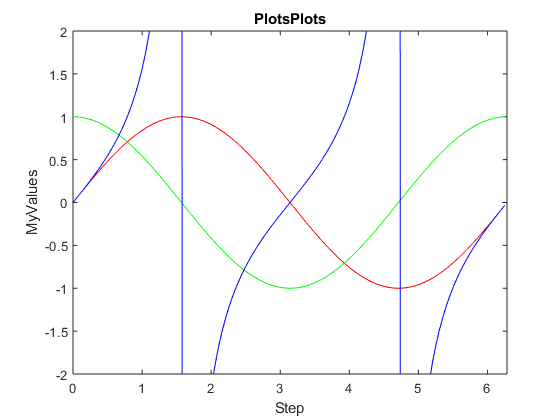


steps = 0:0.05:2*pi;
sinValues = sin(steps);
cosValues = cos(steps);
tanValues = tan(steps);
arcsinValues = asin(steps);
arctanValues = atan(steps);

plot(steps, sinValues, "r",...
     steps, cosValues, "g",...
     steps, tanValues, "b")
 
title("PlotsPlots")
axis([0 2*pi -2 2])
xlabel("Step")
ylabel("MyValues")


subplot(2, 1, 1)

plot(steps, arcsinValues, "c",...
     steps, arctanValues, "m")



title("ArcPlots")
axis([0 2*pi -2 2])
xlabel("Step")
ylabel("YeahValues")


fprintf('\n%s\n', "d)")


d)


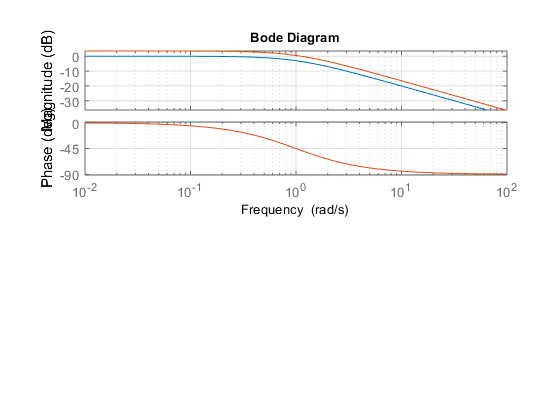

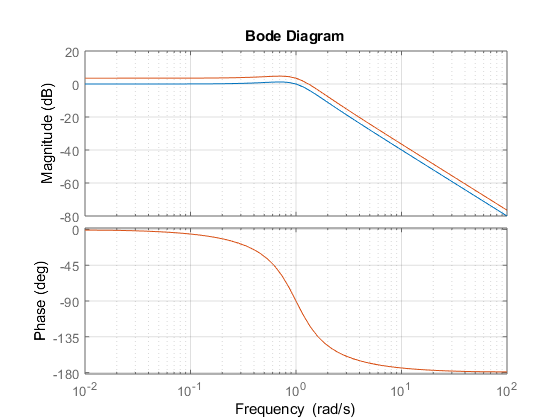


K = [1, 1.5];
T = [1, 5, 10];
d = [0.5, 0.7, 1, 3];

for i = 1:2
    G1 = tf(K(i), [T(1), 1]);
    G2 = tf(K(i), [T(1)^2 2*d(1)*T(1) 1]);
    
    figure(1);
    bode(G1);grid on; hold on;
    title("GPT1 K dynamic");
    
    figure(2);
    bode(G2);grid on; hold on;
    title("GPT2 K dynamic");
end



for i = 1:3
    G1 = tf(K(1), [T(i), 1]);
    G2 = tf(K(1), [T(i)^2 2*d(1)*T(i) 1]);
    
    figure(1);
    bode(G1);grid on; hold on;
    title("GPT1 T dynamic");
    
    figure(2);
    bode(G2);grid on; hold on;
    title("GPT2 T dynamic");
end


for i = 1:4
    G = tf(K(1), [T(1)^2 2*d(i)*T(1) 1]);
    
    figure(1);
    bode(G);grid on; hold on;
    title("GPT2 d dynamic");
end

